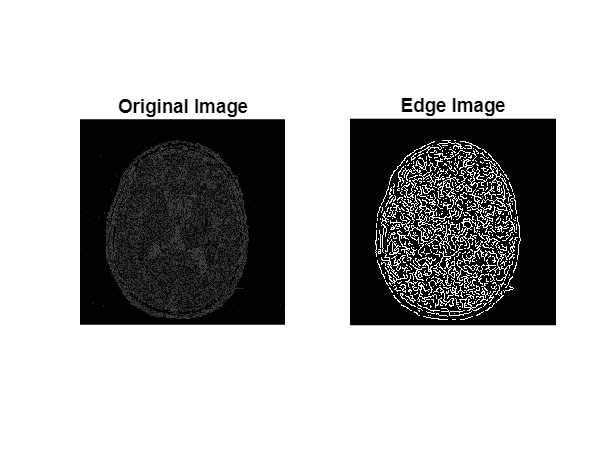

clear all
clc

% Step 1: Reading the image
[file, path] = uigetfile('*.*', 'Select input image');
image = imread(fullfile(path, file));

% Preprocessing: Convert to grayscale if necessary
if size(image, 3) == 3
    image = rgb2gray(image);
end

%image = imread('your_image.jpg'); % Replace 'your_image.jpg' with the path to your image file

% Step 2: Applying CLAHE
clahe_image = adapthisteq(image);

% Step 3: Edge detection using Canny method
edge_image = edge(clahe_image, 'Canny');

% Step 4: Writing the edge image in PNG format
[filepath,name,ext] = fileparts(fullfile(path, file));
ofname=strcat(filepath,'\',name,'_edge.png');
imwrite(edge_image, ofname); % You can replace 'edge_image.png' with the desired output file path

% Displaying the original and processed images
subplot(1,2,1);
imshow(image);
title('Original Image');

subplot(1,2,2);
imshow(edge_image);
title('Edge Image');